# MAIN CODE FILE

- Documentation paragraph that describes what your main code does, in enough detail that a cogent fellow programmer can follow it.

This code controls a wheeled autonomous rover performing a series of three outdoor missions around the Olin Oval. The missions are:

- Waypoint Navigation

- Docking

- Scientific Payload Delivery

This program will prompt the user for a mission number and enter the robot control loop and run the behaviour engine specific to that mission. To find its way around the oval, the rover takes desired location waypoints as inputs. To navigate around potential obstacles in an outdoor environment, the rover has a sensory suite that adds data to a rover-centric occupancy grid. From this grid, a weighted vector (brainwave) is produced that minimizes the potential for collision. Other mission-specific tasks use this concept of brainwave arbitration to determine which steering angle is the best to take.

- Wiring diagram of your robot

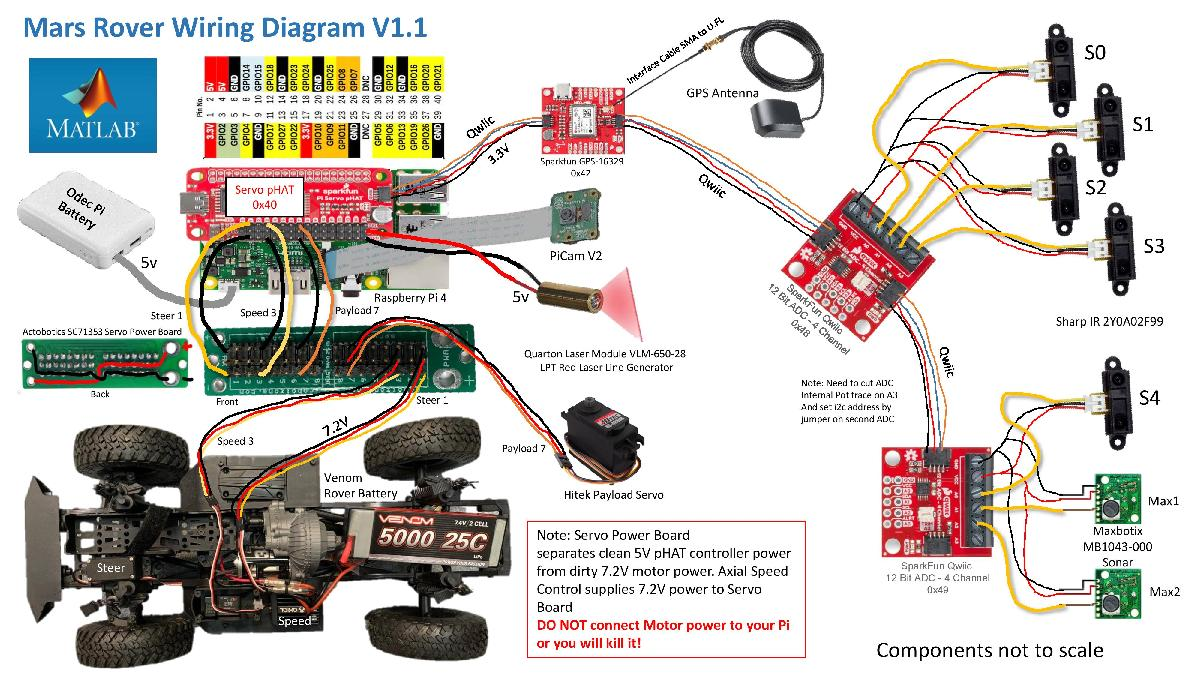

- Clear indication of what external Matlab code parts

The program OlinRoverSetup is used to set up the rover’s Raspberry Pi, sensing and actuation hardware, and create global variables. It's also where mission parameters and data, such as waypoints and the main occupancy grid, are set up.

clc                     % clear command window
clear                   % clear MATLAB workspace
% profile on            % profile used to time each segment of code

## **Set up robot control system** ( code that runs once )

% Set up Raspberry Pi
disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 

At least one END is missing: the statement may begin here.

[robotPi, blinkLED]= RaspPiSetup()

% Turn on board LED on and off to signal program has started 
Blink(robotPi,blinkLED,10);
disp('Warning! Robot Rover Active! ');

% Set up servos, PiCam, and QWIIC analog input
[roverServos, roverJoy] = ServoSetup(robotPi)
[robotCam] = PiCamSetup(robotPi)
[roverServos, roverJoy] = QWIICInputSetup(robotPi)
% TODO: GPS SETUP

**INITIALIZE ROVER OCCUPANCY GRID**

 %Create an empty map of the same dimensions as the test track map
[mapdimx,mapdimy] = size(bwimage);                           %find size of image
roverOccupancyGrid = binaryOccupancyMap(mapdimx,mapdimy,10,'grid');  %make empty map the same size
g
%create a free floating figure
ovalSharpIRScan = figure('name', 'TugSharpIRScan', 'NumberTitle', 'off', 'Visible', 'on');
figure(ovalSharpIRScan)                            
    show(roverOccupancyGrid);                %show the map in a figure window
    grid on;
    grid minor;
    
% figure for live video feed
liveVideo = figure('name', 'ovalVideoFeed', 'NumberTitle', 'off', 'Visible', 'on');

**CREATE GLOBAL VARIABLES**

sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
reset(r);                                          % reset loop time to zero

**ASK FOR MISSION NUMBER**

mission_number = input('Enter mission number: ');

**READY TO RUN ROBOT?**

userInput = questdlg('Ready to run Rover?', 'Start Mission');

## Run Robot Control Loop

if (strcmp(userInput,'Yes'))
    comSteer = 50;                       % set steering center
    comSpeed = 50;                       % set drivespeed to zero
    controlFlag = 1;                     % create a loop control
end

switch mission_number
    case 1 % mission 1: driving
    case 2 % mission 2: docking
    case 3 % mission 3: payload
end

## Robot Functions(store the local functions here)

**SENSE FUNCTIONS**

function[roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid) % fill in other variable
end

function[roverOccupancyGrid] =  SonarRange(roverOccupancyGrid) % fill in other variables
end

function[roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid) % this will be provided from canvas
end

function[roverOccupancyGrid,  dockBearing,  dockRange]  =  PiCamDockFind(roverOccupancyGrid, panAngle, tiltAngle) 
end
 
function[roverOcupancyGrid] = PiCamLaser(roverOcupancyGrid) % laser for obstacle avoidance
end

function[roverOcupancyGrid,  dockBearing,  dockRange]  =  PiCamAprilTagFind(roverOcupancyGrid,panAngle, tiltAngle) %why is there pan and tilt angle
end

**THINK FUNCTIONS**

% think

**ACT FUNCTIONS**

% act